# Dataset Analyzer for INTHIS Integrate System Experiment

This matlab livescript condict analyses on the INTHIS integrated experiment.

clear all; close all; clc;
produce_all_fig=false;

## Build and save the results S.mat struct

This struct is used in all subsequent codes and in Figures

S=struct();
for i=1:8
    Sname=sprintf("S%d",i);
    S.(Sname)=load(fullfile("Results",sprintf("%s.mat",Sname))).Sn;
end
save("S.mat","S");

## Get the meshes

%get data from sources
addpath 'path\to\data_source';

%load NN structure

%get sensorspositions
load sx.csv;
load sy.csv;
load sz.csv;

%get neuronspositions
load xc.csv
load yc.csv;
load zc.csv;
Tri = delaunay(xc,yc);

%get motorpositions
load xm.csv
load ym.csv;
load zm.csv;

%load deltas
load deltax.mat
load deltay.mat
load deltaz.mat

%compute lines
load linex.csv
load liney.csv
load linez.csv

## Get the structures 

%FBG Skin DOMAIN
load FBG_x.csv;
load FBG_y.csv;
load FBG_z.csv;

%FHD DOMAIN
load FHD_x.csv;
load FHD_y.csv;
load FHD_z.csv;

load motor_id_on_FHD.csv;

%ARM DOMAIN
load ARM_xmatrix.csv;
load ARM_ymatrix.csv;
load ARM_zmatrix.csv;

%FHD on FBG
load FHD_on_FBG_x.csv;
load FHD_on_FBG_y.csv;
load FHD_on_FBG_z.csv;

%FHD on ARM
load FHD_on_ARM_x.csv;
load FHD_on_ARM_y.csv;
load FHD_on_ARM_z.csv;

%Ind Coordinates
load xi.csv;
load yi.csv;
load zi.csv;

## Load the results

%load the struct
load S.mat;

## Q0: How did the trials go? subject-wise

The analysis will consider data S2-S8 since S1 was a trial of the experimental setup.

if produce_all_fig
    %subjects
    subjs=["S2","S3","S4","S5","S6","S7","S8"];
    
    tic
    for s=1:length(subjs)
        
        %get the subject
        Sn=subjs(s);
        
        for t=1:72
    
            %get the trial
            Tn=sprintf("T%d",t);
            
            try
                %get the spike data
                fbgs=S.(Sn).(Tn).FBGs;
                neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
                motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
                roi=S.(Sn).(Tn).ROI;
                ind=S.(Sn).(Tn).Ind;
                
                %find the ROI
                EXP_id_on_FHD = inellipse(FHD_x,FHD_y, roi(2), roi(3), roi(4), roi(5), roi(6));
                
                %threshold the fbgs
                fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
                
                %compute the firing rates
                neuronsFR=computeFR(neurons,900);
                motorsFR=computeFR(motors,23);
                
                %create figure
                fig=figure(Visible="off");
                set(gcf, 'Units', 'Normalized', 'OuterPosition', [0.05 0.05 0.95 0.95]);
                T=tiledlayout(1,2,"TileSpacing","compact","Padding","compact");
                
                %spike data
                tmin=min(neurons(:,1))-1;
                limits=[0 max(neurons(:,1))+1-tmin];
                ax=nexttile(T);
                ax.Visible="off";
                t=tiledlayout(T,3,1,"TileSpacing","compact","Padding","compact");
                
                nexttile(t); data=fbgs; plot(data(:,1)-tmin,data(:,2:end)); grid on; xlim(limits);
                nexttile(t); data=neurons; scatter(data(:,1)-tmin,data(:,2),5,'filled','k'); grid on; xlim(limits); ylim([0 900]); yticks(0:100:901);
                nexttile(t); data=motors; hold on; yticks(1:23); grid on; scatter(data(:,1)-tmin,data(:,2),5,'filled','k'); hold off; xlim(limits); ylim([0 24]);
                
                %visual data in the FBG domain
                nexttile(T); 
                title(sprintf('%s %s',Sn,Tn));
                hold on; view(0,70);
                
                %neurons
                scatter3(xc,yc,zc,30,neuronsFR,'filled','markerFaceAlpha',0.8); 
                trisurf(Tri, xc, yc, zc,neuronsFR,'EdgeAlpha',0.1,'FaceAlpha',0.3);
                scatter3(linex,liney,linez,30,"MarkerFaceColor",[0.0504	0.02980	0.5280],"MarkerFaceAlpha",0.01,"MarkerEdgeColor","none");
                
                %motors
                scatter3(xm,ym,zm,motorsFR*2.5+15,'or','filled','AlphaData',0.8);
                for i=1:length(xm)
                    text(xm(i),ym(i),zm(i)+6,sprintf('%d',i),'Color','k','FontSize',ceil(motorsFR(i)/9)+5,'FontWeight','bold');
                end
                colormap(slanCM('plasma')); clim([0 100]); colorbar;
                
                %plot the user roi
                Tris=delaunay(FHD_on_FBG_x(EXP_id_on_FHD),FHD_on_FBG_y(EXP_id_on_FHD));
                %scatter3(FHD_on_FBG_x(EXP_id_on_FHD),FHD_on_FBG_y(EXP_id_on_FHD),FHD_on_FBG_z(EXP_id_on_FHD),50,'filled','o','MarkerEdgeColor','none','MarkerFaceAlpha',0.8,'MarkerFaceColor','#42e6f5');
                trisurf(Tris,FHD_on_FBG_x(EXP_id_on_FHD),FHD_on_FBG_y(EXP_id_on_FHD),FHD_on_FBG_z(EXP_id_on_FHD),'EdgeColor','#42e6f5','FaceAlpha',1,'FaceColor','#42e6f5');
                
                %try to guess the position with network
                thresh=prctile(neuronsFR,95);
                ix=neuronsFR>=thresh;
                BNNposition=[xc(ix)'*neuronsFR(ix) yc(ix)'*neuronsFR(ix) zc(ix)'*neuronsFR(ix)]/sum(neuronsFR(ix));
                %scatter3(FBGposition(1),FBGposition(2),FBGposition(3),300,'filled','g','MarkerEdgeColor','none','MarkerFaceAlpha',1,'MarkerFaceColor','#f542e6');
                
                %try to guess the position with user
                FHDposition=[mean(FHD_on_FBG_x(EXP_id_on_FHD)) mean(FHD_on_FBG_y(EXP_id_on_FHD)) mean(FHD_on_FBG_z(EXP_id_on_FHD))];
                %scatter3(USERposition(1),USERposition(2),USERposition(3),100,'filled','d','MarkerEdgeColor','none','MarkerFaceAlpha',1,'MarkerFaceColor','b');
                
                %the real position
                %scatter3(REALposition(1),REALposition(2),REALposition(3),30,'filled','g','MarkerEdgeColor','none','MarkerFaceAlpha',1,'MarkerFaceColor','b');
                plotCoin(4.5,[xi(ind),yi(ind),zi(ind)],0.5,100,[0.3 0.3 0.3]);

                %settings
                view(0,90);
                axis equal;
                grid on;
                hold off;
    
                %save and clear
                saveas(fig,fullfile("Figures",sprintf("%s",Sn),sprintf("%s_%s.png",Sn,Tn)));
                delete(fig);
            catch
                fprintf("%s %s nonvalid",Sn,Tn);
            end
        end
        toc
    end
toc
end

## Q1: How is good the FHD in representing the SNN stimuli? Overall

To answer this question we have to compare the centroid of the roi reported by the subjects with the centroid of the SNN activation 

subjs=["S2","S3","S4","S5","S6","S7","S8"];

Es=[];
SEs=[];
for s=1:length(subjs)
    
    %get the subject
    Sn=subjs(s);
    
    for t=1:72

        %get the trial
        Tn=sprintf("T%d",t);
        
        try
            %get the FHD ROI and its centre
            ind=S.(Sn).(Tn).Ind;

            %exclude the regions that are not well represented in the two domains
            if or(ind<=9, ind>=64)
                continue;
            end

            %get the FHD ROI and its centre
            roi=S.(Sn).(Tn).ROI;
            centroid=[roi(2) roi(3)];
            jstar=dsearchn([FHD_x FHD_y],[roi(2) roi(3)]);
            FHDposition=[FHD_on_FBG_x(jstar) FHD_on_FBG_y(jstar) FHD_on_FBG_z(jstar)];
    
            %get the BNN ROI and its centre
            neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1;
            neuronsFR=computeFR(neurons,900);
            thresh=prctile(neuronsFR,95);
            ix=neuronsFR>=thresh;
            BNNposition=[xc(ix)'*neuronsFR(ix) yc(ix)'*neuronsFR(ix) zc(ix)'*neuronsFR(ix)]/sum(neuronsFR(ix));
           
    
            %compute the error between the two
            E=BNNposition-FHDposition; 
            Es=[Es; E];
            SEs=[SEs; norm(E)^2];
        catch
            fprintf("%s %s nonvalid",Sn,Tn);
        end
        
    end
end

S3 T72 nonvalidS5 T63 nonvalidS5 T64 nonvalidS5 T65 nonvalidS5 T66 nonvalidS5 T67 nonvalidS5 T68 nonvalidS5 T69 nonvalidS5 T70 nonvalidS5 T71 nonvalidS5 T72 nonvalidS7 T72 nonvalid

%compute the RMSE
RMSE=sqrt(mean(SEs))

RMSE = 17.5323

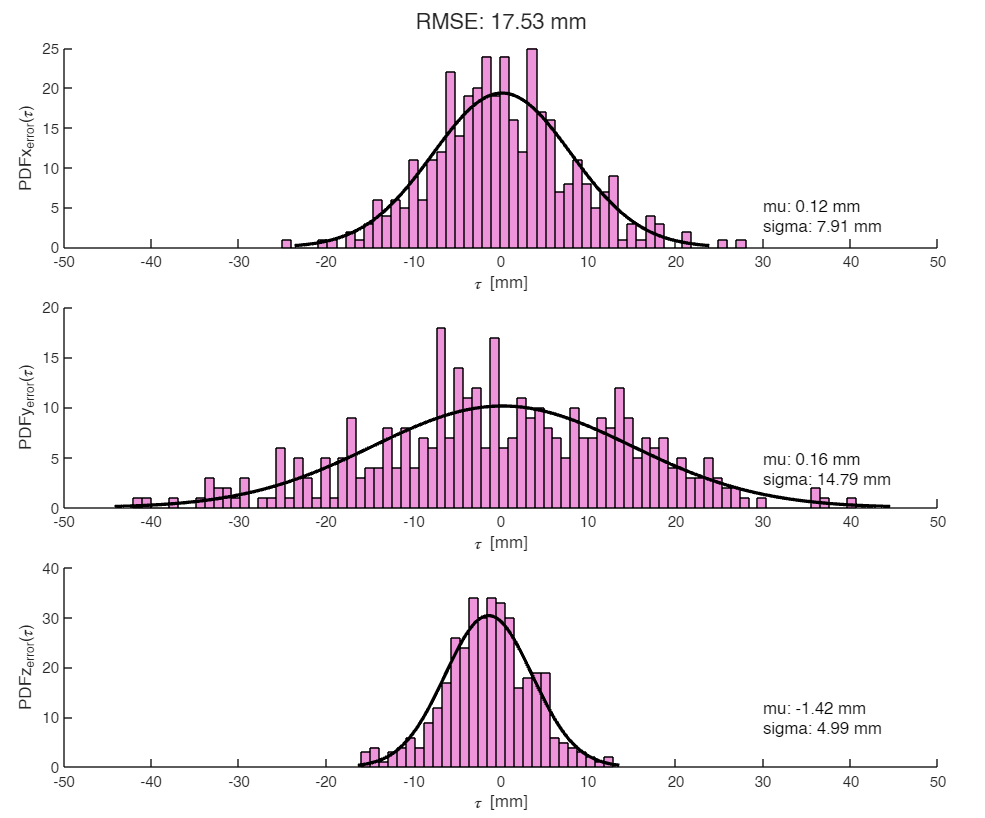

%show the distribution
fig=figure('Position',[170 50 880 730]);
binwidth=1;
t=tiledlayout(3,1,"TileSpacing","compact","Padding","compact");
title(t,sprintf("RMSE: %.2f mm",RMSE));

nexttile;
hold on;
E=Es(:,1);
ExBNN_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd);
h1(1).FaceColor = [.93 .58 .86];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFx_{error}(\tau)'); xlim([-50 50]);

nexttile;
hold on;
E=Es(:,2);
EyBNN_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.93 .58 .86];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFy_{error}(\tau)'); xlim([-50 50]);


nexttile;
hold on;
E=Es(:,3);
EzBNN_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.93 .58 .86];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,10,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFz_{error}(\tau)'); xlim([-50 50]);

## Test for the gaussianity of distribution

The results tall that to the 1% level of significance the data are Gaussian.

[h,p] = chi2gof(ExBNN_FHD,'Alpha',0.01)

h = 0

p = 0.1940

[h,p] = chi2gof(EyBNN_FHD,'Alpha',0.01)

h = 0

p = 0.2390

[h,p] = chi2gof(EzBNN_FHD,'Alpha',0.01)

h = 0

p = 0.1535

## Test the 0 mean hypothesis

1: Using t-test

[h,p] = ttest(ExBNN_FHD,0,'Alpha',0.01)

h = 0

p = 0.7759

[h,p] = ttest(EyBNN_FHD,0,'Alpha',0.01)

h = 0

p = 0.8363

[h,p] = ttest(EzBNN_FHD,0,'Alpha',0.01)

h = 1

p = 8.7653e-08

2: Using Wilcoxon Signed Ranked test.

[h,p] = signrank(ExBNN_FHD,0,"alpha",0.01)

h = 0.8927

p = logical
   0


[h,p] = signrank(EyBNN_FHD,0,"alpha",0.01)

h = 0.6060

p = logical
   0


[h,p] = signrank(EzBNN_FHD,0,"alpha",0.01)

h = 1.9330e-07

p = logical
   1


## Q2: How is good the SNN in representing the FBG SKin stimuli? Overall

To answer this question we have to compare the centroid of the roi reported by the subjects with the centroid of the SNN activation 

subjs=["S2","S3","S4","S5","S6","S7","S8"];

Es=[];
SEs=[];
for s=1:length(subjs)
    
    %get the subject
    Sn=subjs(s);
    
    for t=1:72

        %get the trial
        Tn=sprintf("T%d",t);
        
        try
            %get the FBG Skin Indentation and its centre
            ind=S.(Sn).(Tn).Ind;
            FBGposition=[xi(ind) yi(ind) zi(ind)];

            %regions to exclude
            if  or(ind<=9,ind>=64)
                continue;
            end
    
            %get the BNN ROI and its centre
            neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1;
            neuronsFR=computeFR(neurons,900);
            thresh=prctile(neuronsFR,95);
            ix=neuronsFR>=thresh;
            BNNposition=[xc(ix)'*neuronsFR(ix) yc(ix)'*neuronsFR(ix) zc(ix)'*neuronsFR(ix)]/sum(neuronsFR(ix));
    
            %compute the error between the two
            E=FBGposition-BNNposition; 
            Es=[Es; E];
            SEs=[SEs; norm(E)^2];
        catch
            fprintf("%s %s nonvalid",Sn,Tn);
        end
    end
end

S3 T72 nonvalidS5 T63 nonvalidS5 T64 nonvalidS5 T65 nonvalidS5 T66 nonvalidS5 T67 nonvalidS5 T68 nonvalidS5 T69 nonvalidS5 T70 nonvalidS5 T71 nonvalidS5 T72 nonvalidS7 T72 nonvalid

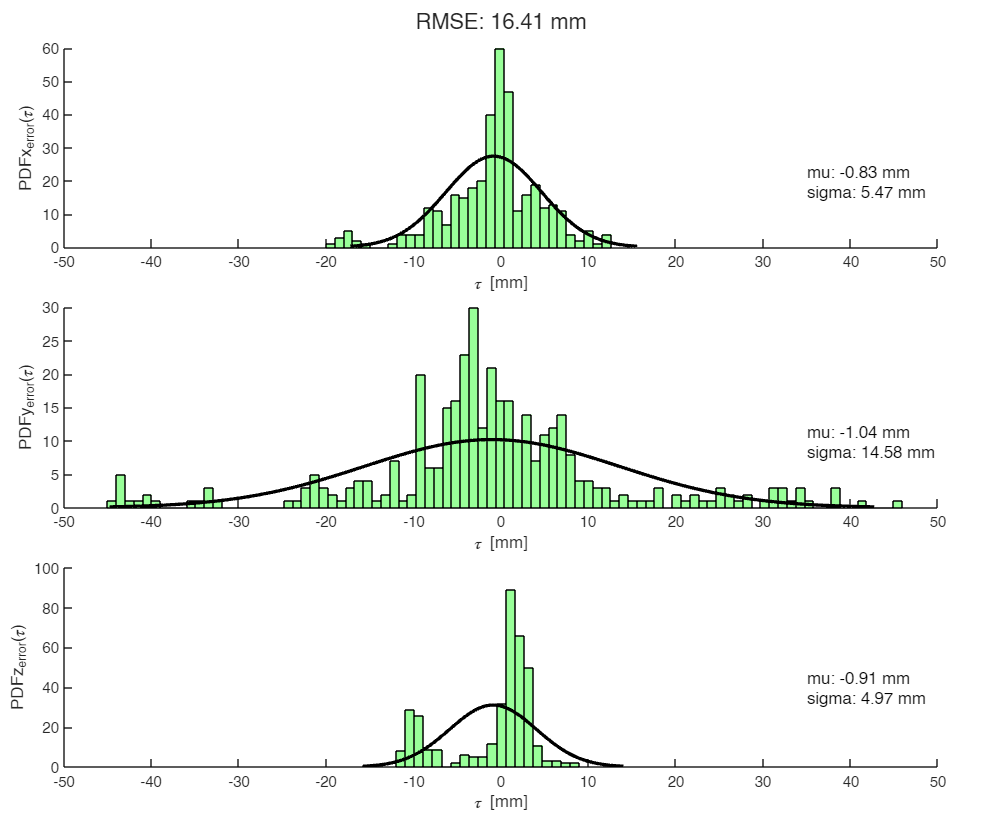

%compute the RMSE
RMSE=sqrt(mean(SEs));

%show the distribution
fig=figure('Position',[170 50 880 730]);
binwidth=1;
t=tiledlayout(3,1,"TileSpacing","compact","Padding","compact");
title(t,sprintf("RMSE: %.2f mm",RMSE));

nexttile;
hold on;
E=Es(:,1);
ExFBG_BNN=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd);
h1(1).FaceColor = [.6 1 .6];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(35,20,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFx_{error}(\tau)'); xlim([-50 50]);

nexttile;
hold on;
E=Es(:,2);
EyFBG_BNN=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.6 1 .6];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(35,10,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFy_{error}(\tau)'); xlim([-50 50]);


nexttile;
hold on;
E=Es(:,3);
EzFBG_BNN=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.6 1 .6];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(35,40,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFz_{error}(\tau)'); xlim([-50 50]);

saveas(fig,fullfile("Figures","BNNwrtFBG_overall.png"));

## Test for the gaussianity of distribution

The results tall that to the 1% level of significance the data are not Gaussian.

[h,p] = chi2gof(ExFBG_BNN,'Alpha',0.01)

h = 1

p = 1.1771e-04

[h,p] = chi2gof(EyFBG_BNN,'Alpha',0.01)

h = 1

p = 1.2957e-18

[h,p] = chi2gof(EzFBG_BNN,'Alpha',0.01)

h = 1

p = 1.1122e-77

## Test the 0 mean hypothesis

1: Using t-test.

[h,p] = ttest(ExFBG_BNN,0,'Alpha',0.01)

h = 1

p = 0.0038

[h,p] = ttest(EyFBG_BNN,0,'Alpha',0.01)

h = 0

p = 0.1696

[h,p] = ttest(EzFBG_BNN,0,'Alpha',0.01)

h = 1

p = 4.9048e-04

2: Using Wilcoxon Signed Ranked test.

[h,p] = signrank(ExFBG_BNN,0,"alpha",0.01)

h = 0.0220

p = logical
   0


[h,p] = signrank(EyFBG_BNN,0,"alpha",0.01)

h = 0.0204

p = logical
   0


[h,p] = signrank(EzFBG_BNN,0,"alpha",0.01)

h = 0.2219

p = logical
   0


## Q3: How is good the FHD in representing the FBG Skin stimuli? Overall

To answer this question we have to compare the centroid of the roi reported by the subjects with the real positions over the skin 

subjs=["S2","S3","S4","S5","S6","S7","S8"];

Es=[];
SEs=[];
Rs=[];
for s=1:length(subjs)
    
    %get the subject
    Sn=subjs(s);
    
    for t=1:72

        %get the trial
        Tn=sprintf("T%d",t);
        
        try
            %get the FHD ROI and its centre
            roi=S.(Sn).(Tn).ROI;
            centroid=[roi(2) roi(3)];
            jstar=dsearchn([FHD_x FHD_y],[roi(2) roi(3)]);
            FHDposition=[FHD_on_FBG_x(jstar) FHD_on_FBG_y(jstar) FHD_on_FBG_z(jstar)];
    
            %get the FBG Skin Indentation and its centre
            ind=S.(Sn).(Tn).Ind;
            FBGposition=[xi(ind) yi(ind) zi(ind)];

            if or(ind<=9,ind>=64)
                continue;
            end
            
            %compute the error between the two
            E=FBGposition-FHDposition; 
            Es=[Es; E];
            SEs=[SEs; norm(E)^2];

            %compute the parameters of the elliptical ROI
            R=max([roi(4) roi(5)]);
            Rs=[Rs; R];

        catch
            fprintf("%s %s nonvalid",Sn,Tn);
        end
    end
end

S3 T72 nonvalidS5 T63 nonvalidS5 T64 nonvalidS5 T65 nonvalidS5 T66 nonvalidS5 T67 nonvalidS5 T68 nonvalidS5 T69 nonvalidS5 T70 nonvalidS5 T71 nonvalidS5 T72 nonvalidS7 T72 nonvalid

%compute the RMSE
RMSE=sqrt(mean(SEs))

RMSE = 23.9676

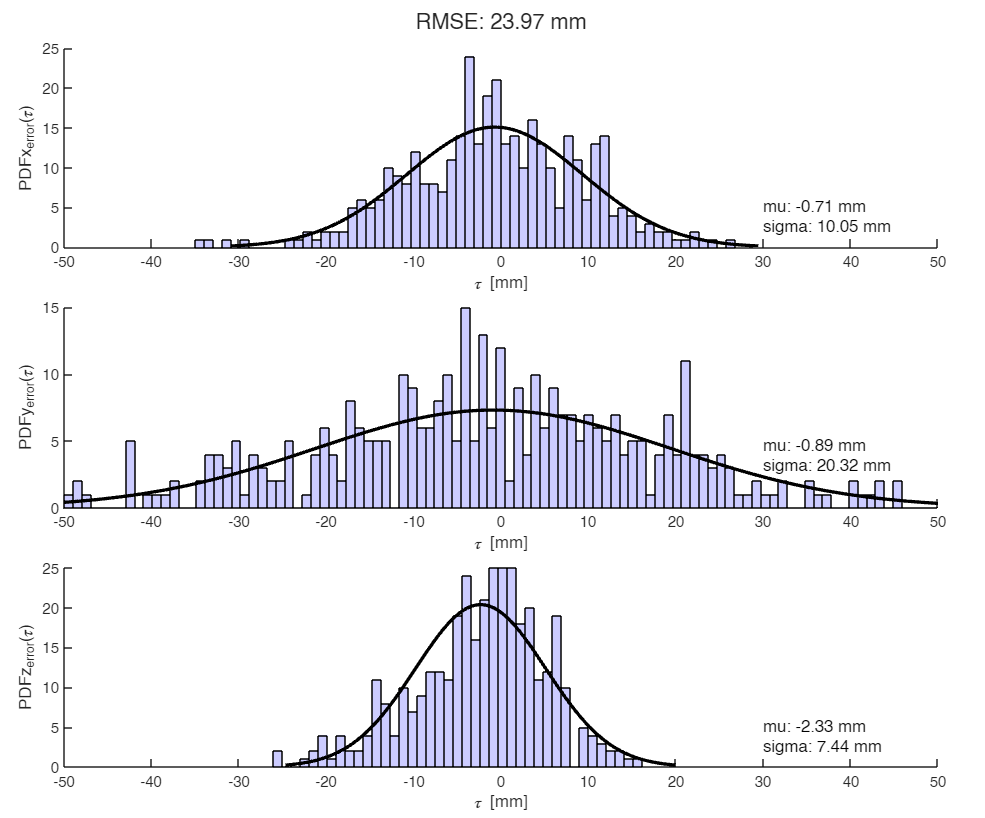


%show the distribution
fig=figure('Position',[170 50 880 730]);
binwidth=1;
t=tiledlayout(3,1,"TileSpacing","compact","Padding","compact");
title(t,sprintf("RMSE: %.2f mm",RMSE));

nexttile;
hold on;
E=Es(:,1);
ExFBG_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd);
h1(1).FaceColor = [.8 .8 1];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFx_{error}(\tau)'); xlim([-50 50]);

nexttile;
hold on;
E=Es(:,2);
EyFBG_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.8 .8 1];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFy_{error}(\tau)'); xlim([-50 50]);


nexttile;
hold on;
E=Es(:,3);
EzFBG_FHD=E;
pd=fitdist(E,"Normal");
h1=histfit(E,floor((max(E)-min(E))/binwidth),"normal",pd); 
h1(1).FaceColor = [.8 .8 1];
h1(2).Color = [0 0 0];
h1(2).LineWidth=2;
text(30,4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFz_{error}(\tau)'); xlim([-50 50]);

## Test for the gaussianity of distribution

The results tall that to the 1% level of significance the data are Gaussian.

[h,p] = chi2gof(ExFBG_FHD,'Alpha',0.01)

h = 0

p = 0.0386

[h,p] = chi2gof(EyFBG_FHD,'Alpha',0.01)

h = 0

p = 0.2824

[h,p] = chi2gof(EzFBG_FHD,'Alpha',0.01)

h = 1

p = 8.0823e-04

## Test the 0 mean hypothesis

1: Using t-test.

[h,p] = ttest(ExFBG_FHD,0,'Alpha',0.01)

h = 0

p = 0.1748

[h,p] = ttest(EyFBG_FHD,0,'Alpha',0.01)

h = 0

p = 0.4032

[h,p] = ttest(EzFBG_FHD,0,'Alpha',0.01)

h = 1

p = 4.4556e-09

2: Using Wilcoxon Signed Ranked test.

[h,p] = signrank(ExFBG_FHD,0,"alpha",0.01)

h = 0.2409

p = logical
   0


[h,p] = signrank(EyFBG_FHD,0,"alpha",0.01)

h = 0.4242

p = logical
   0


[h,p] = signrank(EzFBG_FHD,0,"alpha",0.01)

h = 5.4543e-07

p = logical
   1


## Test the correlation between the subcomponents with spearman

There is no significant correlation.

Ex=[ExFBG_BNN ExBNN_FHD];
[rho,pval]=corr(Ex,'type','Spearman')

rho =     1.0000    0.0841
    0.0841    1.0000


pval =     1.0000    0.1067
    0.1067    1.0000


Ey=[EyFBG_BNN EyBNN_FHD];
[rho,pval]=corr(Ey,'type','Spearman')

rho =     1.0000   -0.0045
   -0.0045    1.0000


pval =     1.0000    0.9307
    0.9307    1.0000


Ez=[EzFBG_BNN EzBNN_FHD];
[rho,pval]=corr(Ez,'type','Spearman')

rho =     1.0000    0.0449
    0.0449    1.0000


pval =     1.0000    0.3893
    0.3893    1.0000


rho =     1.0000    0.8419
    0.8419    1.0000


pval =     1.0000    0.0000
    0.0000    1.0000


rho =     1.0000    0.7338
    0.7338    1.0000


pval =     1.0000    0.0000
    0.0000    1.0000


rho =     1.0000    0.7297
    0.7297    1.0000


pval =     1.0000    0.0000
    0.0000    1.0000


## Additional Analysis of the errors

This first analysis demonstrates that, for the entire dataset:

More than 45% of the trials ended with the IND falling inside the subjective ROI

For the 54% outside trials, the distance between the IND and the ROI is significatively lower (p<6.25 e-6) than the characteriastic ROI dimension (assumed to be the equal to the ellipse main axis).

%For each trial:

match=0;
valid=0;
Es=[];
Rs=[];

for s=2:8
    %subject
    Sn=sprintf("S%d",s);

    for n=1:72
        try
            %get the indentation
            Tn=sprintf("T%d",n);
        
            %get the spike data
            fbgs=S.(Sn).(Tn).FBGs;
            neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
            motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
            roi=S.(Sn).(Tn).ROI;
            ind=S.(Sn).(Tn).Ind;
        
             if or(ind<=9,ind>=64)
                continue;
            end
            
            
            %the center of the indentation position in FBG skin domain
            indpoint=[xi(ind) yi(ind) zi(ind)];
            ix=dsearchn([FHD_on_FBG_x FHD_on_FBG_y FHD_on_FBG_z],indpoint);

            %create a circle within the indpoint with area 65mm^2
            radius=sqrt(65/pi);
            distances=pdist2([FHD_on_FBG_x FHD_on_FBG_y FHD_on_FBG_z],[xi(ind) yi(ind) zi(ind)]);
            IND_ids_on_FHD=distances<=radius;
            
            %find the ROI
            ROI_ids_on_FHD = inellipse(FHD_x,FHD_y, roi(2), roi(3), roi(4), roi(5), roi(6));

        
            %first trial: find if the ROI comprises the dot
            if any(ismember(find(IND_ids_on_FHD),find(ROI_ids_on_FHD)))
                %if it is comprised save the match
                match=match+1;
            else
                %compute the distance between closer IND and ROI point
                distances2=pdist2([FHD_x(IND_ids_on_FHD) FHD_y(IND_ids_on_FHD)],[FHD_x(ROI_ids_on_FHD) FHD_y(ROI_ids_on_FHD)]);
                E=min(distances2(:));
                Es=[Es; E];
                R=max([roi(4) roi(5)]);
                Rs=[Rs; R]; 
            end
           

            valid=valid+1;
    
        catch
            fprintf("Subject %s, Trial %s not available",Sn,Tn);
        end
    
    end
end

Subject S3, Trial T72 not availableSubject S5, Trial T63 not availableSubject S5, Trial T64 not availableSubject S5, Trial T65 not availableSubject S5, Trial T66 not availableSubject S5, Trial T67 not availableSubject S5, Trial T68 not availableSubject S5, Trial T69 not availableSubject S5, Trial T70 not availableSubject S5, Trial T71 not availableSubject S5, Trial T72 not availableSubject S7, Trial T72 not available

perc=100*match/valid

perc = 45.2575

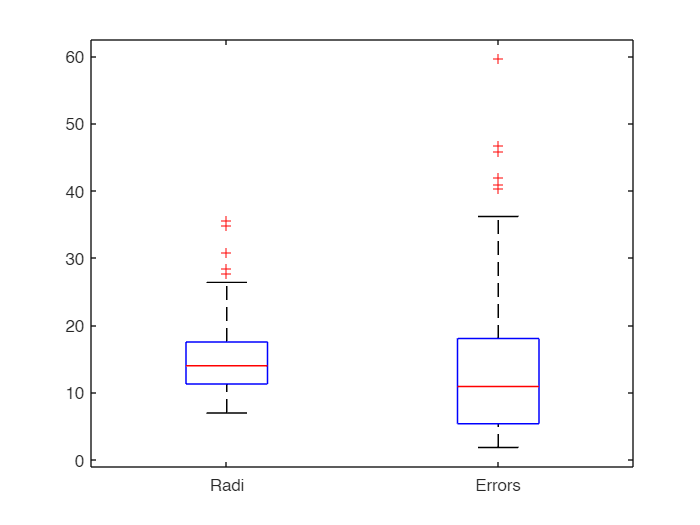

v1=Rs;
v2=Es;

ydata=[v1 v2];
names={'Radi','Errors'};
figure;
boxplot(ydata,names);

%establish if the data are normally distrubited 
[h1,p1] = kstest(v1)

h1 = logical
   1


p1 = 1.5304e-178

[h2,p2] = kstest(v2)

h2 = logical
   1


p2 = 6.2870e-166

Compare their Variances :

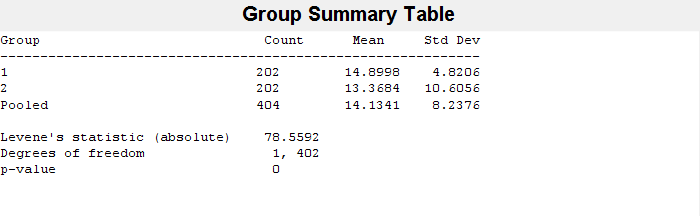

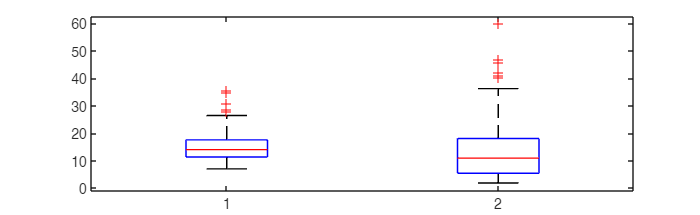

data=[v1; v2];
group=[ones(202,1); 2*ones(202,1)];

[p,stats] = vartestn(data, group, 'TestType', 'LeveneAbsolute','Display','on');

Since their variances are different, the two populations are tested with Generalized Wilcoxon test, implemented in scipy.stats in a custom python notebook.

## Additional analysis of the Extensions

This additional analysis tries to demonstrate that there is a close match between the extension of the SNN activation cloud and the ROI dimension drawn by the subject at the different trials.

What it demonstrates is that, considered:

     A1 as the area of the SNN II layer activation

    A2 as the area of the elliptical ROI drawn by the subject

There is a significant positive correlation (rho=0.12, p<0.05) between the two areas.

Subject S2:

...............................

Number of elements : 54

...............................

h = 0

p = 0.3996

h = 0

p = 0.0887

...............................

rho =     1.0000    0.3618
    0.3618    1.0000


pval =     1.0000    0.0075
    0.0075    1.0000


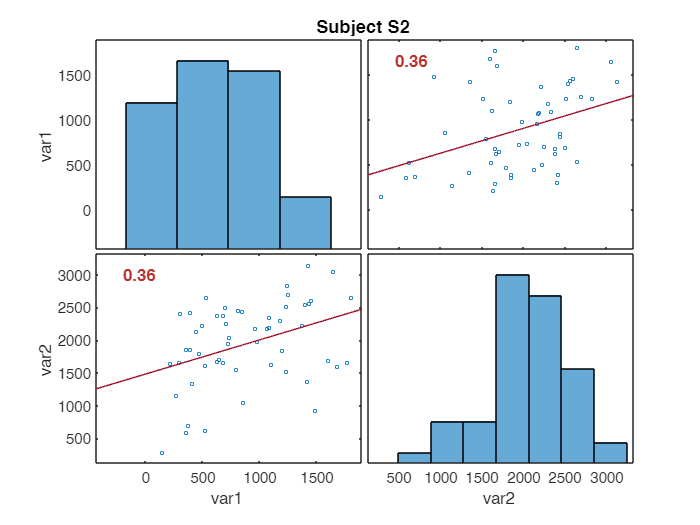

Subject S3, Trial T72 not available

Subject S3:

...............................

Number of elements : 54

...............................

h = 0

p = 0.0219

h = 0

p = 0.0874

...............................

rho =     1.0000    0.1436
    0.1436    1.0000


pval =     1.0000    0.2994
    0.2994    1.0000


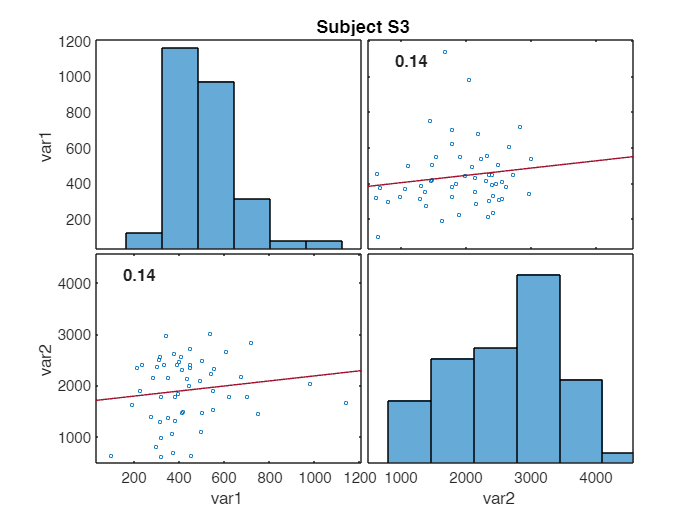

Subject S4:

...............................

Number of elements : 54

...............................

h = 0

p = 0.4238

h = 0

p = 0.0851

...............................

rho =     1.0000    0.2711
    0.2711    1.0000


pval =     1.0000    0.0477
    0.0477    1.0000


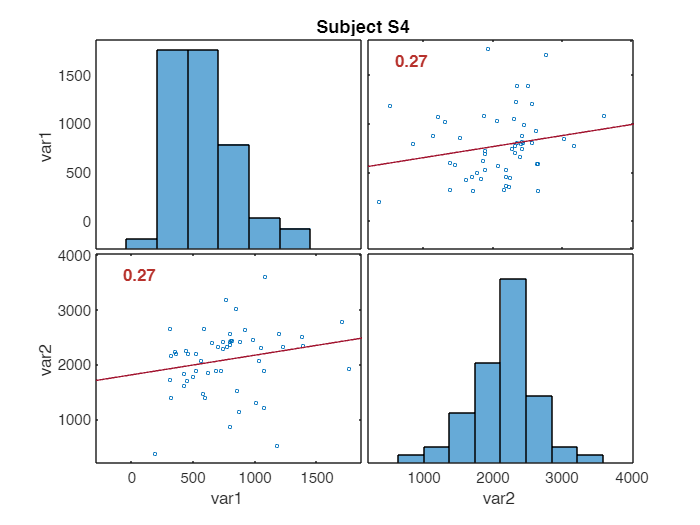

Subject S5, Trial T63 not availableSubject S5, Trial T64 not availableSubject S5, Trial T65 not availableSubject S5, Trial T66 not availableSubject S5, Trial T67 not availableSubject S5, Trial T68 not availableSubject S5, Trial T69 not availableSubject S5, Trial T70 not availableSubject S5, Trial T71 not availableSubject S5, Trial T72 not available

Subject S5:

...............................

Number of elements : 46

...............................

h = 1

p = 0.0071

h = 0

p = 0.0357

...............................

rho =     1.0000    0.4436
    0.4436    1.0000


pval =     1.0000    0.0022
    0.0022    1.0000


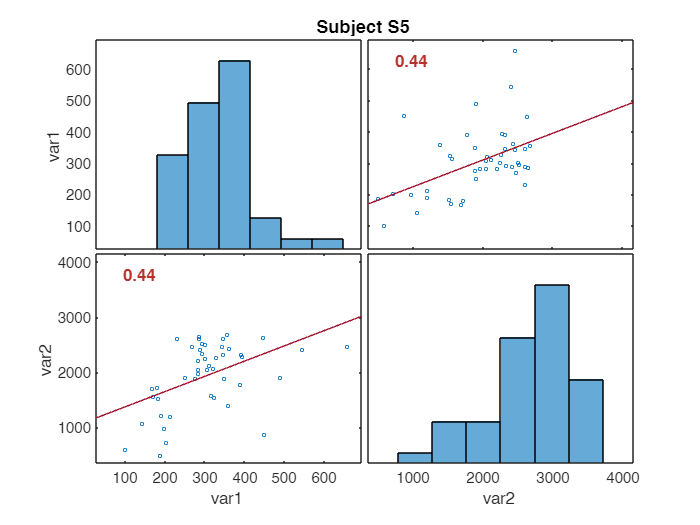

Subject S6:

...............................

Number of elements : 54

...............................

h = 1

p = 1.2875e-05

h = 0

p = 0.0152

...............................

rho =     1.0000    0.4199
    0.4199    1.0000


pval =     1.0000    0.0017
    0.0017    1.0000


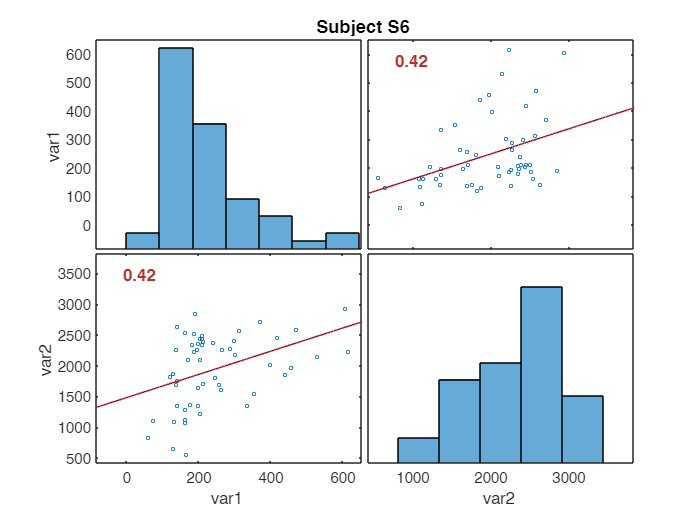

Subject S7, Trial T72 not available

Subject S7:

...............................

Number of elements : 53

...............................

h = 0

p = 0.0667

h = 0

p = 0.3586

...............................

rho =     1.0000    0.1971
    0.1971    1.0000


pval =     1.0000    0.1567
    0.1567    1.0000


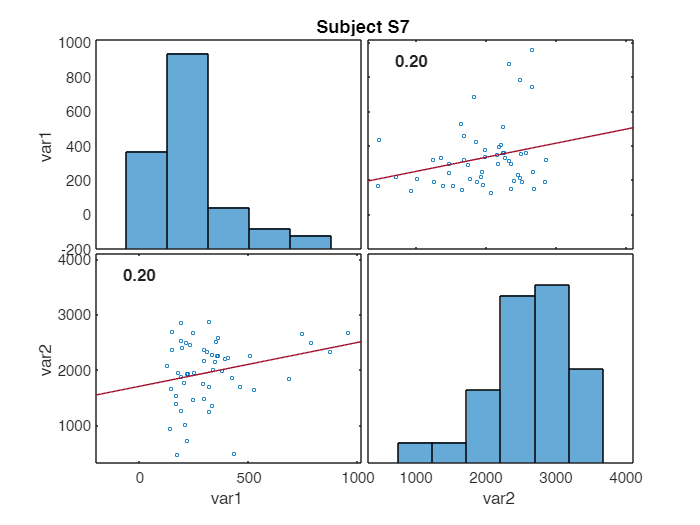

Subject S8:

...............................

Number of elements : 54

...............................

h = 1

p = 0.0022

h = 0

p = 0.0657

...............................

rho =     1.0000    0.4710
    0.4710    1.0000


pval =     1.0000    0.0004
    0.0004    1.0000


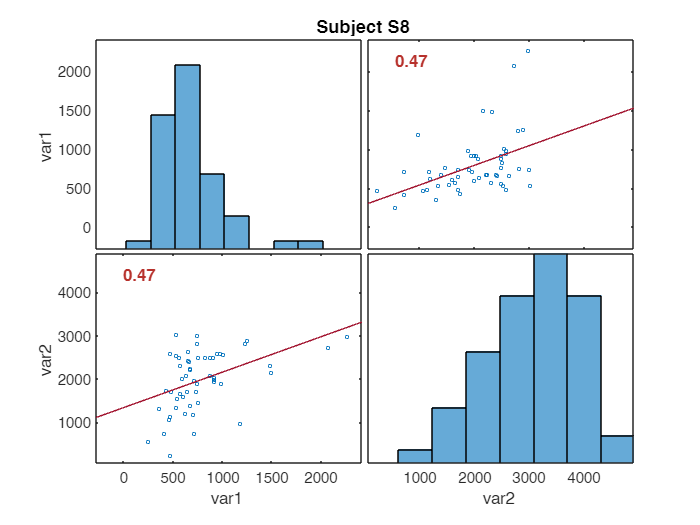

showthefigure=0;

FRthresh=1;

ROI_all=[];
SNN_all=[];

for s=2:8
    
    %subject
    Sn=sprintf("S%d",s);
    ROI_areas=[];
    SNN_areas=[];

    
    for n=1:72

        try
            %get the indentation
            Tn=sprintf("T%d",n);
        
            %get the spike data
            fbgs=S.(Sn).(Tn).FBGs;
            neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
            motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
            roi=S.(Sn).(Tn).ROI;
            ind=S.(Sn).(Tn).Ind;
            
            %jump in case
             if or(ind<=9,ind>=64)
                continue;
             end
            
            %find the ROI in FHD domain
            ROI_ids_on_FHD = inellipse(FHD_x,FHD_y, roi(2), roi(3), roi(4), roi(5), roi(6));

            %compute the area of the ROI region
            A1=[FHD_x(ROI_ids_on_FHD) FHD_y(ROI_ids_on_FHD)];
            k1=convhull(A1);
            ROI_hull_area = polyarea(A1(k1, 1), A1(k1, 2));

            %get the neuronal activation of second and third layer and transform them to FHD-wise indexes
            neuronsFR=computeFR(neurons,900);
            neurons_ids_on_FBG=neuronsFR>FRthresh;
            [k1,av1]=convhulln([xc(neurons_ids_on_FBG) yc(neurons_ids_on_FBG) zc(neurons_ids_on_FBG)]);
            SNN_ids_on_FHD=inhull([FHD_on_FBG_x FHD_on_FBG_y FHD_on_FBG_z],[xc(neurons_ids_on_FBG) yc(neurons_ids_on_FBG) zc(neurons_ids_on_FBG)],k1);
            
            %compute the area of the SNN region
            A2=[FHD_x(SNN_ids_on_FHD) FHD_y(SNN_ids_on_FHD)];
            k2=convhull(A2);
            SNN_hull_area = polyarea(A2(k2, 1), A2(k2, 2));

            ROI_areas=[ROI_areas; ROI_hull_area];
            SNN_areas=[SNN_areas; SNN_hull_area];
           
            if showthefigure
                %show
                figure; tiledlayout(1,2);
                
                nexttile;
                hold on;
                % trisurf(k1,xc(neurons_ids_on_FBG),yc(neurons_ids_on_FBG),zc(neurons_ids_on_FBG),'FaceColor','cyan','FaceAlpha',0.4,'EdgeAlpha',0.4)
                
                %neurons
                scatter3(xc,yc,zc,30,neuronsFR,'filled','markerFaceAlpha',0.8); 
                trisurf(Tri, xc, yc, zc,neuronsFR,'EdgeAlpha',0.1,'FaceAlpha',0.3);
                scatter3(linex,liney,linez,30,"MarkerFaceColor",[0.0504	0.02980	0.5280],"MarkerFaceAlpha",0.01,"MarkerEdgeColor","none");
                
                %fhd points
                scatter3(FHD_on_FBG_x(SNN_ids_on_FHD),FHD_on_FBG_y(SNN_ids_on_FHD),FHD_on_FBG_z(SNN_ids_on_FHD),10,'or','filled','markerFaceAlpha',1);
                axis equal;
                hold off; 
    
                nexttile; hold on;
    
                %the FHD mesh
                scatter3(FHD_x,FHD_y,FHD_z,4,'filled','o','MarkerEdgeColor','none','MarkerFaceAlpha',0.8,'MarkerFaceColor','#808080');
                
                %the motor posiitons
                for i=1:length(motor_id_on_FHD)
                    P=[FHD_x(motor_id_on_FHD(i)),FHD_y(motor_id_on_FHD(i)),FHD_z(motor_id_on_FHD(i))];
                    L=[5,15,1];
                    O = P-L/2 ;
                    O(2)=O(2)-L(2)/2;
                    O(3)=O(3)-1;
                    plotcube(L,O,.8,[0.7 0.7 0.7]);
                    L=[8,3,1.1];
                    O = P-L/2 ;
                    O(3)=O(3)-1;
                    plotcube(L,O,.8,[0 0 0]);
                    text(O(1)+2,O(2)-10,O(3)+5,sprintf('%d',i),"FontSize",15,'Color','k','FontWeight','bold');
                end
    
                %the SNN region
                scatter3(FHD_x(SNN_ids_on_FHD),FHD_y(SNN_ids_on_FHD),FHD_z(SNN_ids_on_FHD),10,'or','filled','markerFaceAlpha',1);
                
                %the ROI
                scatter3(FHD_x(ROI_ids_on_FHD),FHD_y(ROI_ids_on_FHD),FHD_z(ROI_ids_on_FHD),10,'oc','filled','markerFaceAlpha',1);
    
    
                %settings
                axis equal; grid on; %title(ax,'FHD DOMAIN');
                xlabel('x [mm]'); ylabel('y [mm]'); zlabel('z [mm]'); view(0,90);
                hold off; legend(ax,'FHD points','Location','northeast');
            end
        catch
            fprintf("Subject %s, Trial %s not available",Sn,Tn);
        end
    end
    fprintf("Subject %s:",Sn);
    fprintf("...............................")
    fprintf("Number of elements : %d",length(ROI_areas))
    fprintf("...............................")
    [h,p] = chi2gof(ROI_areas,'Alpha',0.01)
    [h,p] = chi2gof(SNN_areas,'Alpha',0.01)

    fprintf("...............................")
    data=[ROI_areas SNN_areas];
    [rho,pval]=corr(data,'type','Spearman')
    figure; hold on; 
    corrplot(data,Type="Spearman",TestR="on");
    title(sprintf("Subject %s", Sn));

    ROI_all=[ROI_all; ROI_areas];
    SNN_all=[SNN_all; SNN_areas];
end


%Now for ALL
[h,p] = chi2gof(ROI_all,'Alpha',0.01)

h = 1

p = 3.0312e-13

[h,p] = chi2gof(SNN_all,'Alpha',0.01)

h = 1

p = 7.0672e-08

data=[ROI_all SNN_all];
[rho,pval]=corr(data,'type','Spearman')

rho =     1.0000    0.2511
    0.2511    1.0000


pval =     1.0000    0.0000
    0.0000    1.0000


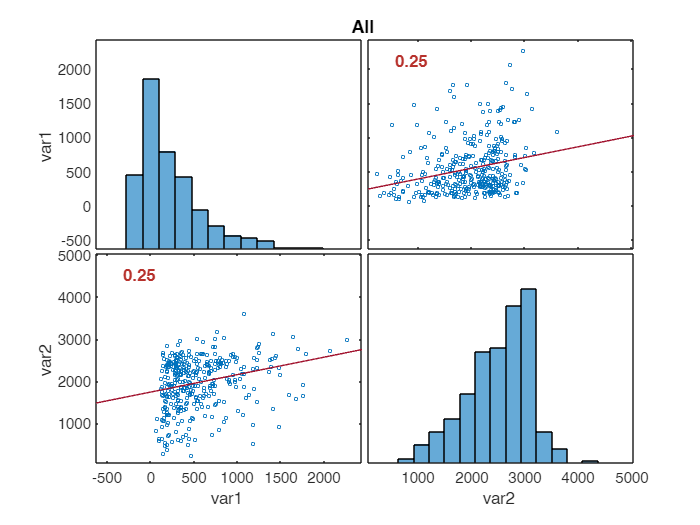

figure; hold on; 
corrplot(data,Type="Spearman",TestR="on");
title("All");